Construction of a function over the unit disk is straightforward. We define a grid in $(r,\theta)$ space and compute accordingly. For the function $f(r,\theta)=1-r^4$, for example:

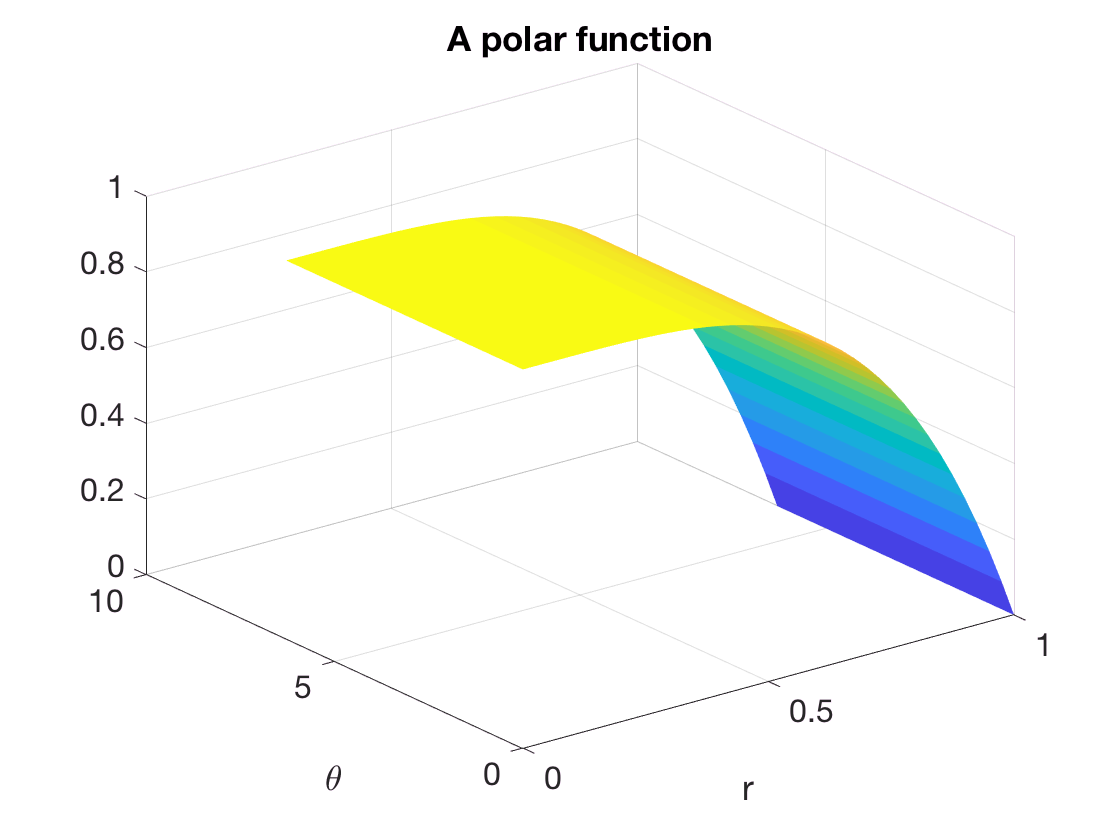

r = linspace(0,1,41);
theta = linspace(0,2*pi,81);
[R,Theta] = ndgrid(r,theta);
F = 1-R.^4;
surf(R,Theta,F)
shading flat    % ignore this line
xlabel('r'), ylabel('\theta'), title('A polar function')    % ignore this line

Of course we are used to seeing such plots over the $(x,y)$ plane. This is easily accomplished.

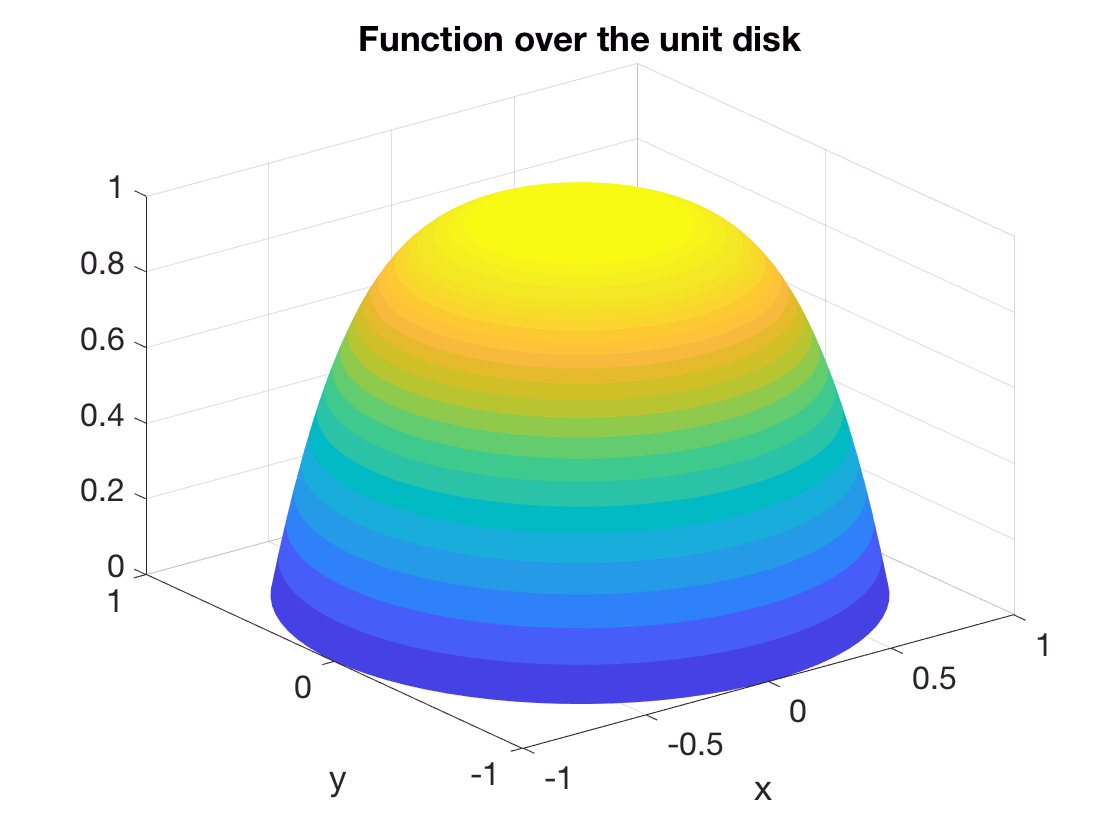

X = R.*cos(Theta);  Y = R.*sin(Theta);
surf(X,Y,F)
shading flat    % ignore this line
xlabel('x'), ylabel('y'), title('Function over the unit disk')    % ignore this line

In such functions it's up to us to ensure that the values along the line $r=0$ are identical, and that the values on the line $\theta=0$ are identical to those on $\theta=2\pi$. Otherwise the interpretation of the domain as the unit disk is nonsensical.

On the unit sphere we can use color to indicate a function value. For the function $f(x,y,z)=xyz^3$, for instance:

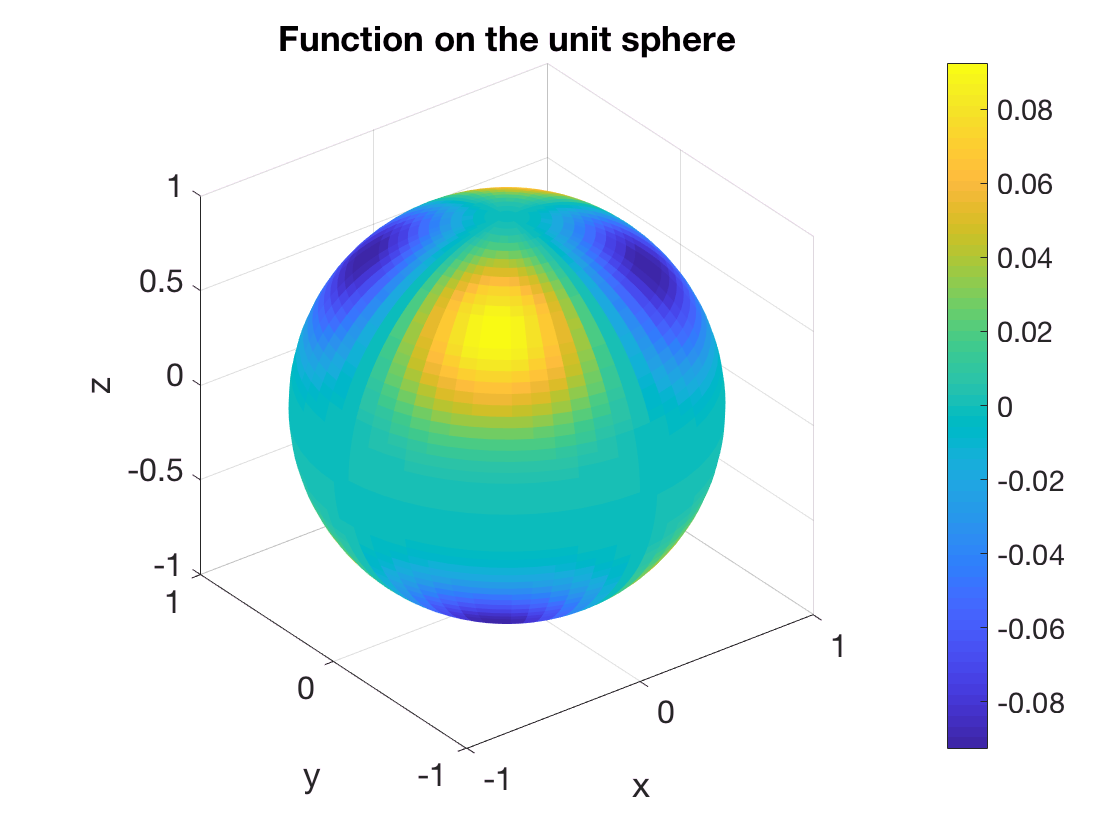

theta = linspace(0,2*pi,61);
phi = linspace(0,pi,61);
[Theta,Phi] = ndgrid(theta,phi);
X = cos(Theta).*sin(Phi); Y = sin(Theta).*sin(Phi); 
Z = cos(Phi);
F = X.*Y.*Z.^3;
surf(X,Y,Z,F), colorbar
axis equal, shading flat     % ignore this line
xlabel('x'), ylabel('y'), zlabel('z')    % ignore this line
title('Function on the unit sphere')     % ignore this line